# Find Spots for every Channel

This script is used for detecting the signals in each channel for direct RNA ISS. 

The fist step is to specify the path of the file analysed. We have 5 files including a single channel on the same image each (4 Detection channels+DAPI). The files are name equally (have the same prefix) but have a different number each after the prefix, specifying the channel.

folder='L:\4plex_assay\200313_r1c1\200313_cDNA_01__tr2_rd1cy1001\Preprocess\Stitched2DTiles_MIST_Ref1\'

folder = 'L:\4plex_assay\200313_r1c1\200313_cDNA_01__tr2_rd1cy1001\Preprocess\Stitched2DTiles_MIST_Ref1\'

PREFIX='200313_cDNA_01__tr2_rd1cy1001_stitched-'

PREFIX = '200313_cDNA_01__tr2_rd1cy1001_stitched-'

## Finding spots channel 1

We load the image containnig channel 1 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(1),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, 0.001); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 1 it will be SIG1

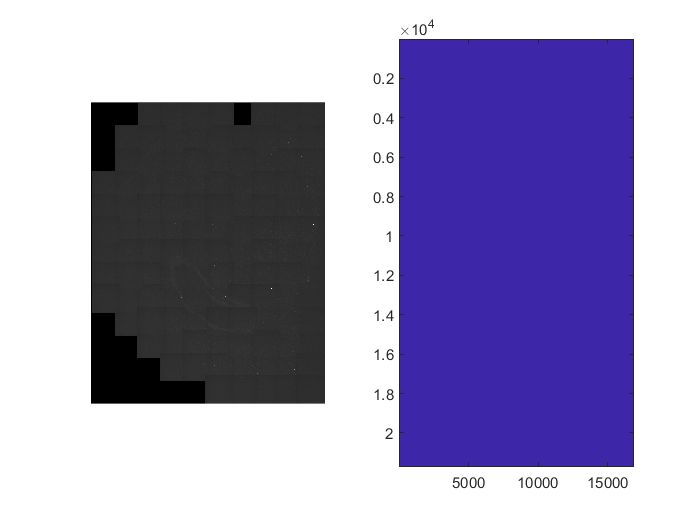

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =         4291           1



 SIG1=[blobs,XY];
 GROUP=1*ones(size(SIG1,1),1);
 SIG1=[SIG1,GROUP];

## Finding spots channel 2

We load the image containnig channel 2 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(2),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, 0.0025); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 2 it will be SIG2

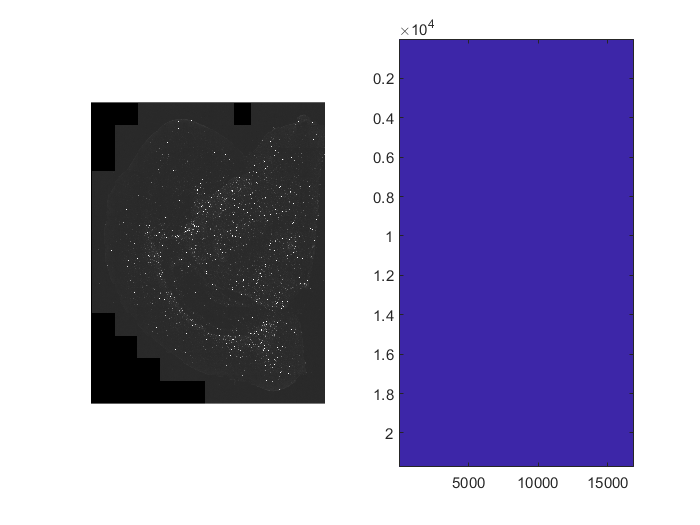

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =       192008           1



 SIG2=[blobs,XY];
 GROUP=2*ones(size(SIG2,1),1);
 SIG2=[SIG2,GROUP];

## Finding spots channel 3

We load the image containnig channel 3 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(3),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, .002); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 3 it will be SIG3

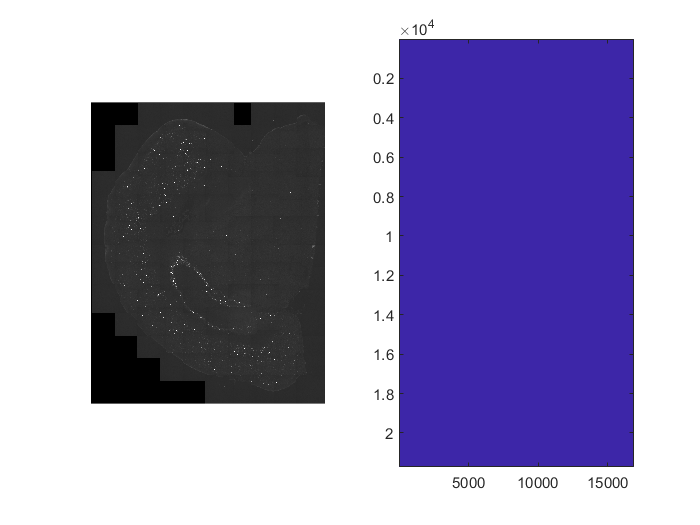

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =       106514           1



 SIG3=[blobs,XY];
 GROUP=3*ones(size(SIG3,1),1);
 SIG3=[SIG3,GROUP];

## Finding spots channel 4

We load the image containnig channel 4 on Itop and we detect the signal.

We specify a intensity threshold for the detection of signal. This value will vary in order to accurately differentiate between what a spot is and what it's not.


Itop=imread([folder,PREFIX,num2str(4),'.tif']);
% %% reference segmentation
I = double(Itop)/65535;
I=Itop;
I = imtophat(I, strel('disk', 2));
Ibw = im2bw(I, .002); %This value needs to be customized


We plot in paralel both images (raw and binary) in order to check whether we capture true signal. If we do not capture accurately the true signals, we will need to modify the previous thresholds.


figure;
subplot(1,2,1);
imshow(Itop*100);
subplot(1,2,2);
imshow(Ibw*100);
linkaxes();


We finally detect the signals by applying watershed and bwareopen. We save the coordinates of the spots in a SIG file. In this case, for Channel 4 it will be SIG4

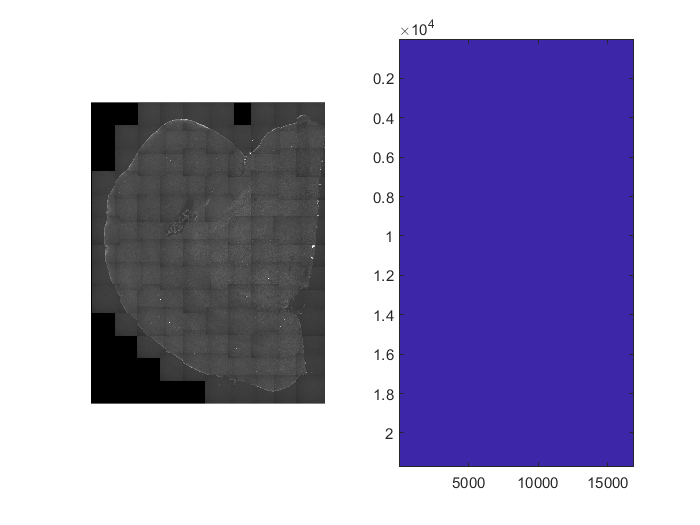

Iws = watershed(-I);
Iws = double(Iws) .* double(Ibw);
Ibw = logical(Iws);
Ibw = bwareaopen(Ibw, 3);
image(Iws);

Ibw = logical(Iws);

UNIQUES = bwconncomp(Iws);
U2=labelmatrix(UNIQUES);
%U2=uint16(U2);
pr=regionprops(U2);
XY=fliplr(vertcat(regionprops(U2).Centroid));

 [blobs] = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =        13753           1



 SIG4=[blobs,XY];
 GROUP=4*ones(size(SIG4,1),1);
 SIG4=[SIG4,GROUP];

### Save detected spots

The spots detected in all channels are combined in a matrix and saved in a file

ALL=[SIG1(:,1:4);SIG2(:,1:4);SIG3(:,1:4);SIG4(:,1:4)];
writematrix(ALL,[folder,PREFIX,'_SPOTS_found','.csv']);

### Plot spots found

We first load the DAPI,which in our case is in channel 5. Then, we plot all together

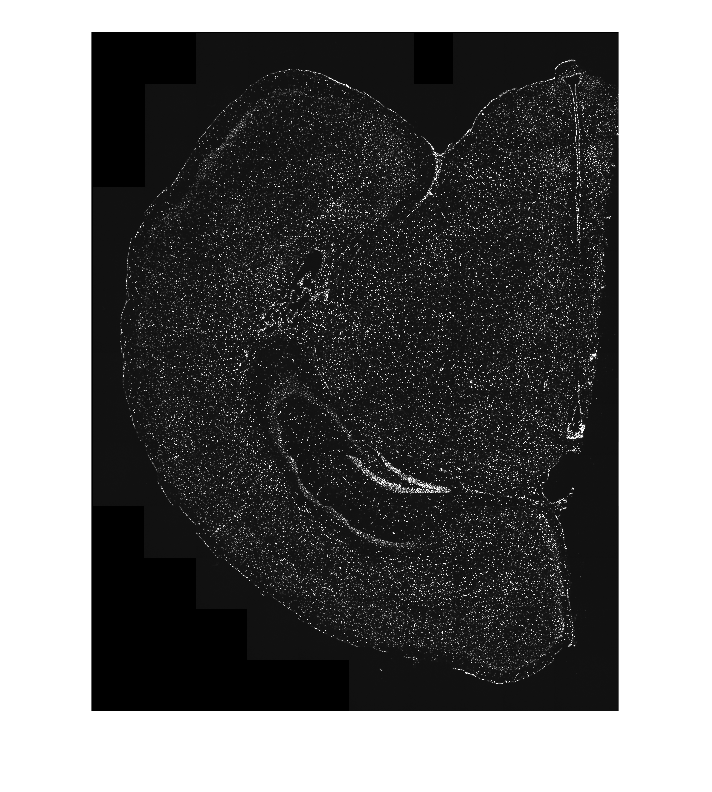

IDAPI=imread([folder,PREFIX,num2str(5),'.tif']);
figure
imshow(IDAPI*40);
hold on 
gscatter(SIG2(:,3),SIG2(:,2),[],'m','.',0.01,'filled')
hold on
gscatter(SIG1(:,3),SIG1(:,2),[],'c','.',0.01,'filled')
hold on
gscatter(SIG4(:,3),SIG4(:,2),[],'g','.',0.01,'filled')
hold on

gscatter(SIG3(:,3),SIG3(:,2),[],'y','.',0.01,'filled')


##  Assigning Signal to DAPI

 %WORKING WITH DAPI

IDAPI=imread([folder,PREFIX,num2str(5),'.tif']);

Dapi = imadjust(IDAPI); % contrast enhancement
ImSz = size(Dapi);
Debug = 1;
%% threshold the map
ThreshVal = 35000;

bwDapi = imerode(Dapi>ThreshVal, strel('disk', 2));

if Debug
    figure(300)
    subplot(2,1,1);
    imagesc(Dapi); 
    subplot(2,1,2);
    imagesc(bwDapi);
    colormap bone
    fprintf('Threshold = %f\n', ThreshVal);
    linkaxes();
end

Threshold = 35000.000000


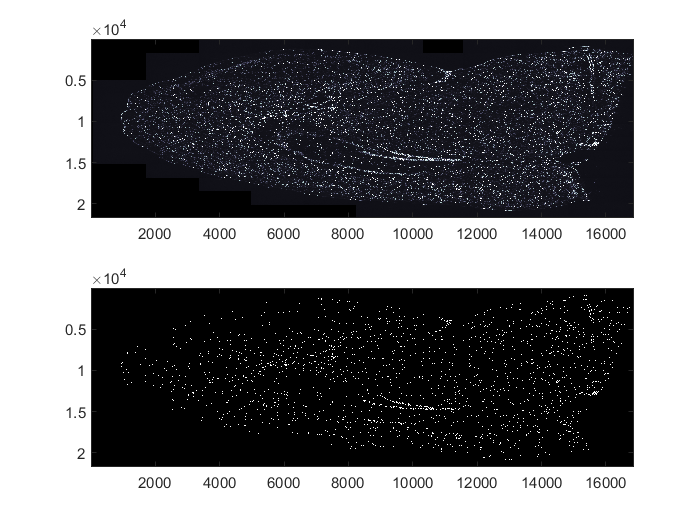

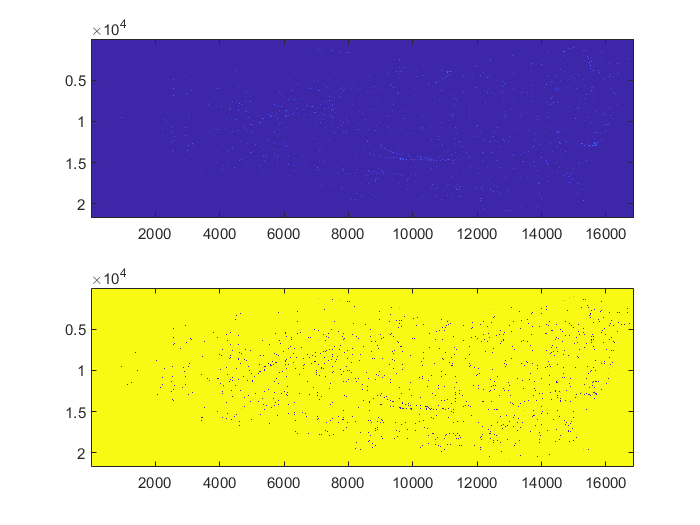

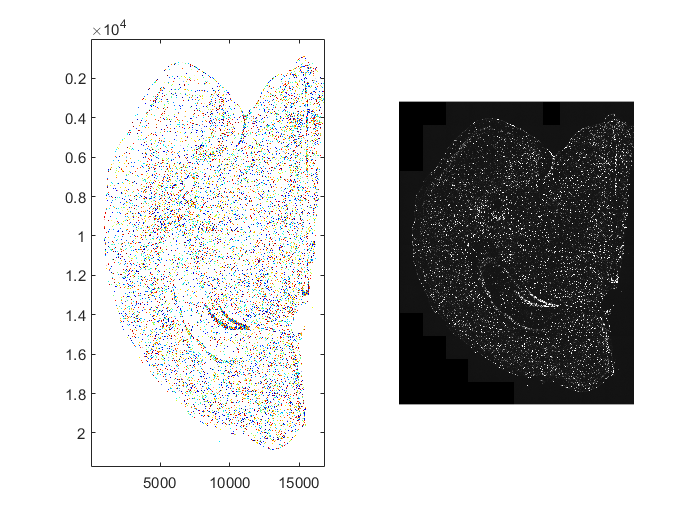

%% find local maxima 
dist = bwdist(~bwDapi);
dist0 = dist;
dist0(dist<5)=0;


ddist = imdilate(dist0, strel('disk', 7));
%clear dist 
impim = imimposemin(-dist0, imregionalmax(ddist));
clear dist0
if Debug
    figure(301);
    subplot(2,1,1)
    imagesc(dist);
    subplot(2,1,2)
    imagesc(impim);
end
%% segment
% remove pixels at watershed boundaries
bwDapi0 = bwDapi;
bwDapi0(watershed(impim)==0)=0;

% assign all pixels a label
labels = uint32(bwlabel(bwDapi0));
[d, idx] = bwdist(bwDapi0);

% now expand the regions by a margin
CellMap0 = zeros(ImSz, 'uint32');
Expansions = (d<10);
CellMap0(Expansions) = labels(idx(Expansions));

% get rid of cells that are too small
rProps0 = regionprops(CellMap0); % returns XY coordinate and area
BigEnough = [rProps0.Area]>200;
NewNumber = zeros(length(rProps0),1);
NewNumber(~BigEnough) = 0;
NewNumber(BigEnough) = 1:sum(BigEnough);
CellMap = CellMap0;
CellMap(CellMap0>0) = NewNumber(CellMap0(CellMap0>0));

if Debug
    figure(302)
    subplot(1,2,1);
    image(label2rgb(CellMap, 'jet', 'w', 'shuffle'));
    subplot(1,2,2);
    imshow(Dapi);
    linkaxes();
end


%%

%UNIQUES = bwconncomp(Ibw);
U2=CellMap;
 blobs = unique(U2);
 blobs = blobs(blobs~=0);
 size(blobs)

ans =        54467           1


 XtotD=[];
 YtotD=[];
 Position4=[];
 Position1=[];
 Position2=[];
 Position3=[];
 SIZE=[];
 for totblob = 1:size(blobs)
 disp(totblob)
 [X,Y]=find(U2==blobs(totblob));
 XtotD=[XtotD,mean(X)];
 YtotD=[YtotD,mean(Y)];
 SIZE=[SIZE,size(X,1)];
 Position1=[Position1,sum(ismember(SIG1(:,2),X)& ismember(SIG1(:,3),Y))];
 Position2=[Position2,sum(ismember(SIG2(:,2),X)& ismember(SIG2(:,3),Y))];
 Position3=[Position3,sum(ismember(SIG3(:,2),X)& ismember(SIG3(:,3),Y))];
  Position4=[Position4,sum(ismember(SIG4(:,2),X)& ismember(SIG4(:,3),Y))];
 end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



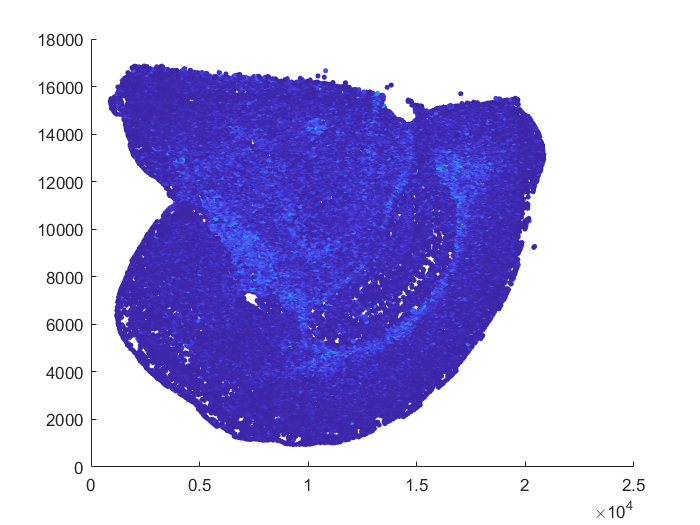

figure
SIGdapi=[blobs,XtotD',YtotD',Position1',Position2',Position3',Position4',SIZE']; 
scatter(XtotD,YtotD,10,Position2,'filled');


writematrix(SIGdapi,[folder,PREFIX,'_ASSIGN_READ_CELL','.csv']);